# PLVZ: Pl2 LFP file Visualizer----Education Edition

#### PLVZ contains abundant feature such as: PSD histogram drawing, heatmap generation, waterfall 3d mapping.

*FC210001 has strongest 40Hz entrainment*

**Sampling Rate (f****s****�****):**

- The sampling rate is the number of samples per second taken from a continuous signal to create a discrete signal. It is measured in **Hz** (samples per second).

- According to the **Nyquist theorem**, the sampling rate must be at least twice the highest frequency component of the signal to avoid aliasing.

**Frequency Resolution (**Δf\Delta f**Δ****f****):**

- Frequency resolution is the smallest distinguishable frequency difference that can be detected in a frequency spectrum. It is determined by the total time duration of the signal (TTT).

- Mathematically:

Δf=$\frac{1}{T}$

- where TTT is the total duration of the signal (the reciprocal of the **frequency resolution** is the time span of the analyzed signal).

�

addpath(genpath("resource"))
addpath("output")
 
clear;
% enter pl2 file name
% [pl2.file,pl2.path] = uigetfile("*.pl2");
% pl2fullfile = "data\LFP20240725\LFP\shrna-40-a110001.pl2";
pl2fullfile = "data\LFP20240723\FC210001.pl2";
% pl2fullfile = "data\LFP20240628\trkb\40HZ-a321001.pl2";
[pl2.path,pl2.name] = fileparts(pl2fullfile)

pl2 = struct with fields:
    path: "data\LFP20240723"
    name: "FC210001"


pl2 = struct with fields:
    path: "data\LFP20240723"
    name: "FC210001"



addpath(pl2.path)

pl2.ind = PL2GetFileIndex(pl2fullfile);

PL2Print(pl2.ind.AnalogChannels) % print out channels name

[cell#]         PlxChannel          NumValues               Name         SourceName             Source            Channel            Enabled   RecordingEnabled              Units   SamplesPerSecond CoeffToConvertToUn    SourceTrodality              Trode     ChannelInTrode NumberOfChannelsIn           DeviceId NumberOfChannelsIn   SourceDeviceName    ProbeDeviceName      ProbeSourceId ProbeSourceChannel      ProbeDeviceId ProbeDeviceChannel InputVoltageMinimu InputVoltageMaximu          TotalGain     InternalArray1     InternalArray2     InternalArray3
      1                  0                  0               WB01                 WB                  3                  1                  1                  0              Volts              40000    1.948759778e-07                  1                  1                  1                 32                552                 32 Digital HST Proces Generic N-channel                   1                  1                 50                


% Reads A/D data for A/D channel.
%cnl = [4 5 12 13] % enter the number of channel 

% for c = cnl(1:end)
%     pl2.ADdata(c) = PL2Ad(pl2.file, c);
% end

% adfreq:sample rate    n:data points    ts:
chnl = {'FP04','FP05','FP12','FP13'};

% get parameter & create empty vector for mean
[fs, ~, ~, n, ad] = plx_ad_v(pl2fullfile, chnl{1}); % get ad length
format short
t = 1/fs % Sampling period (1 / sampling frequency)

t = 1.0000e-03

timelen = n/fs; % timelength is 600 seconds, n is the length of data
timevec = (0:n-1)*t % time vector

timevec =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490



% =====Downsampling====
dsr = 5; % downsample rate
n = n/dsr;
fs = fs/dsr; % sampling frequncy(fs) change
t = 1/fs % Sampling period (1 / sampling frequency)

t = 0.0050

timelen = n/fs; % timelength is 600 seconds, n is the length of data
timevec = (0:ceil(n-1))*t % time vector

timevec =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


fprintf('downsample: %i', dsr)

downsample: 5

% =====================

matrix_ad = zeros(4,ceil(n)); % specify the sum of ad value for future mean calculation
% Get ad_data for every channel
for x = 1:4
    [~, ~, ~, ~, ad] = plx_ad_v(pl2fullfile, chnl{x});
    if exist('dsr') % if data has been downsampled
        ad = ad(1:dsr:end);
    end
    matrix_ad(x,:) = ad; % store each ad in row
end

% ==mean ad matrix or specific channel==
% OPTION A: average channels
spe_chnl = 'mean'

spe_chnl = 'mean'

mad = mean(matrix_ad)

mad =     0.1777    0.0761    0.0340   -0.0487   -0.1673   -0.2322   -0.2225   -0.2147   -0.2658   -0.2898   -0.2360   -0.2345   -0.1757   -0.1034   -0.1671   -0.1831   -0.1027    0.1469    0.2532    0.2255    0.1604    0.0728    0.1017    0.1555    0.0761    0.0635    0.0885    0.1228    0.0688    0.0520    0.0771    0.0315   -0.0291    0.0033    0.0163   -0.1037   -0.1710   -0.0143   -0.0469   -0.0079   -0.1339   -0.0736    0.1152    0.0839   -0.0405    0.0917    0.0525   -0.0087    0.0707    0.1402


% OPTION B: read specific channel
% spe_chnl = 4; 
% mad = matrix_ad(spe_chnl,:)

% Signal Preprocess

% bandpass
mad = bandpass(mad,[.1 100],fs);

% filter design
% d = designfilt('bandstopiir','FilterOrder',2, ...
%                'HalfPowerFrequency1',49,'HalfPowerFrequency2',51, ...
%                'DesignMethod','butter','SampleRate',fs);
% mad = filtfilt(d, mad);

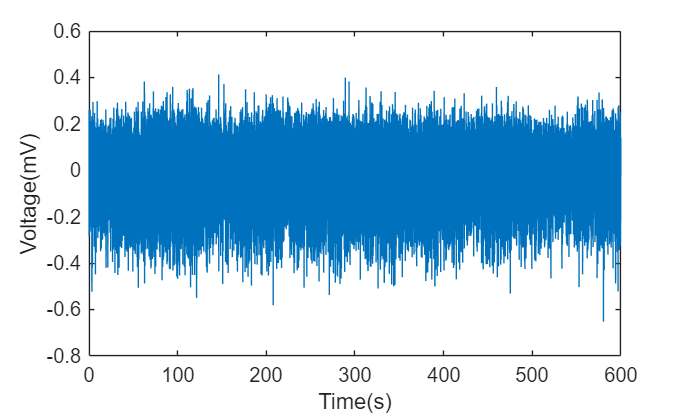

% Plot ad data
plot(timevec,mad)

xlabel('Time(s)')
ylabel('Voltage(mV)')
hold off;

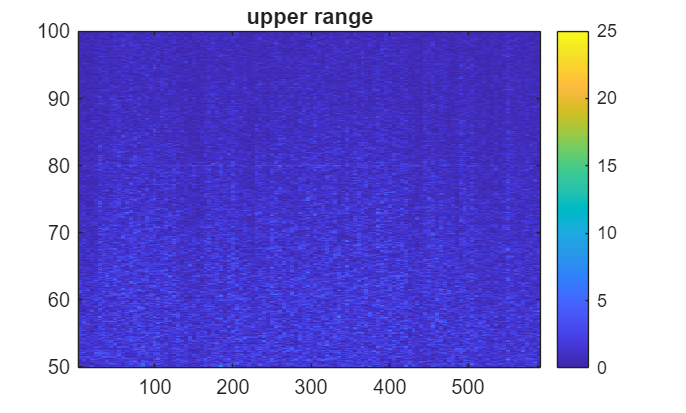

% short-time fast transfrom

opts = {'Window', hamming(2000), 'OverlapLength',1000, 'FFTLength', 2000, 'FrequencyRange', 'onesided'};

[S,F,T] = stft(mad,fs,opts{:});
% upper frequency range map==
upper_range = [50 100];  
% lower frequency range map==
lower_range = [0.1 50];  

% fre_range = [30 50]; 
upper_start_F = floor(length(F)*upper_range(1)/100);
upper_end_F = floor(length(F)*upper_range(2)/100);
lower_start_F = floor(length(F)*lower_range(1)/100);
lower_end_F = floor(length(F)*lower_range(2)/100);

% ==Prune upper scale heatmap
upper_F = F(upper_start_F:upper_end_F);
upper_S = S((upper_start_F:upper_end_F),:);
imagesc(T,upper_F,abs(upper_S(:,:,1)))
set(gca, 'YDir', 'normal');
colorbar;
title('upper range')
caxis([0 25])

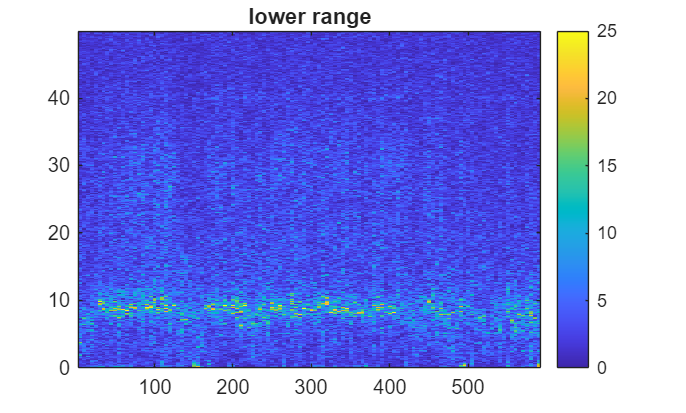


% ==Prune lower scale heatmap
lower_F = F(lower_start_F:lower_end_F);
lower_S = S((lower_start_F:lower_end_F),:);
imagesc(T,lower_F,abs(lower_S(:,:,1)))
set(gca, 'YDir', 'normal');
colorbar;
title('lower range')
caxis([0 25])

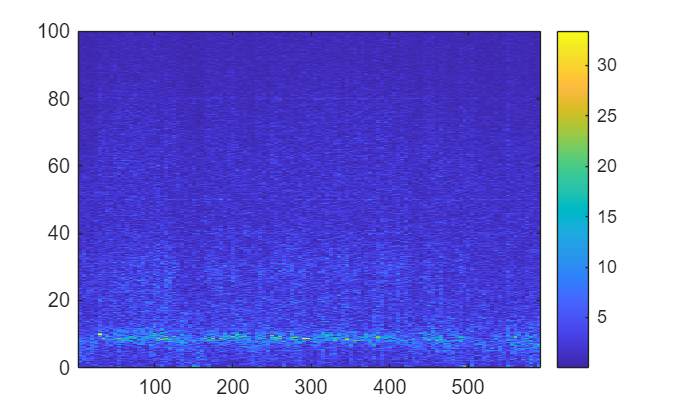


% Save Heatmap Data
% gen_savepath = "output\heatmap\";
% prune_savepath = strcat(gen_savepath,pl2.name,'_chnl',num2str(spe_chnl),'_prune.mat')
% save(prune_savepath,"T", "prune_F", "prune_S") % save heamap data
% prunefig_savepath = erase(prune_savepath,'.mat') % save heatmap fig
% saveas(gca,prunefig_savepath,'fig') % save heatmap figure


% ==Prune scale heatmap






% ==Full scale heatmap
imagesc(T,F,abs(S(:,:,1)))
set(gca, 'YDir', 'normal');
colorbar;

% caxis([0 30])

% Save Heatmap Data
% full_savepath = strcat(gen_savepath,pl2.name,'_chnl',num2str(spe_chnl),'_full.mat')
% save(full_savepath,"T", "F", "S") % save heamap data
% fullfig_savepath = erase(full_savepath,'.mat') % save heatmap fig
% saveas(gca,fullfig_savepath,'fig') % save heatmap figure

% discrete fourier transform
dft = fft(mad);
frevec = fs/n*(0:ceil(n-1)) % frequency vector

frevec =          0    0.0017    0.0033    0.0050    0.0067    0.0083    0.0100    0.0117    0.0133    0.0150    0.0167    0.0183    0.0200    0.0217    0.0233    0.0250    0.0267    0.0283    0.0300    0.0317    0.0333    0.0350    0.0367    0.0383    0.0400    0.0417    0.0434    0.0450    0.0467    0.0484    0.0500    0.0517    0.0534    0.0550    0.0567    0.0584    0.0600    0.0617    0.0634    0.0650    0.0667    0.0684    0.0700    0.0717    0.0734    0.0750    0.0767    0.0784    0.0800    0.0817


nyq = fs/2 %  Nyquist point

nyq = 100

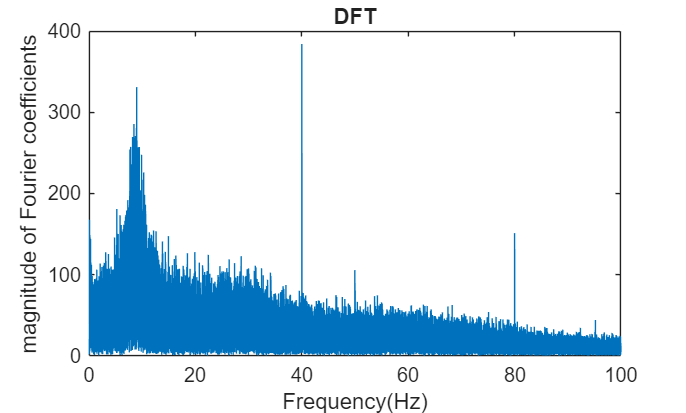

plot(frevec,abs(dft))
xlim([0,nyq])
xlabel('Frequency(Hz)')
ylabel('magnitude of Fourier coefficients')
title('DFT')

% beautiful waterfall

% frequency range limit==
fre_range = [30 50]; 
start_F = floor(length(F)*fre_range(1)/100);
end_F = floor(length(F)*fre_range(2)/100);
prune_F = F(start_F:end_F)

prune_F =    29.9000
   30.0000
   30.1000
   30.2000
   30.3000
   30.4000
   30.5000
   30.6000
   30.7000
   30.8000


prune_S = S((start_F:end_F),:)

prune_S =    1.3166 + 3.6417i   2.6648 + 1.1789i  -0.5753 - 3.1647i  -4.8282 - 1.1879i  -0.2862 + 2.1714i  -2.5666 - 2.7888i   0.8705 + 1.2778i  -0.0532 - 1.2135i  -5.0776 - 0.4627i   0.5334 + 3.9455i   0.2192 - 1.3424i   5.1252 + 0.3568i  -5.2044 + 0.6180i  -5.6035 + 2.7347i   1.0365 + 4.2482i  -0.8505 + 1.3753i   0.3697 - 0.7395i   0.7396 - 2.1027i   1.7225 - 2.1020i  -5.7597 + 3.1687i   5.1596 + 3.6707i   0.9222 + 1.2691i  -4.6001 + 0.7900i   6.0882 - 0.8790i  -0.6098 + 8.8369i  -0.6734 - 2.1720i   0.3182 + 0.0425i  -2.6130 + 1.5465i  -2.9720 - 0.2291i   5.0141 - 0.9768i  -1.5692 + 0.9200i   1.6649 - 0.7520i   1.0714 + 1.2823i   3.2467 - 1.4172i   3.5707 + 1.5996i  -1.0048 - 1.2271i   2.6543 + 1.7651i  -1.4002 - 3.9634i  -0.9988 + 0.3789i  -0.4284 + 5.8134i  -0.4745 - 2.3341i   0.4244 - 0.5841i  -1.5084 + 2.3198i   3.2289 + 0.8336i  -2.0591 - 0.4996i   1.1003 + 1.5530i  -1.0448 + 0.3505i   1.0992 - 0.9515i   0.7255 + 1.4175i   0.1277 - 3.3565i
  -1.8441 - 2.0672i  -2.3671 - 1.5450i 

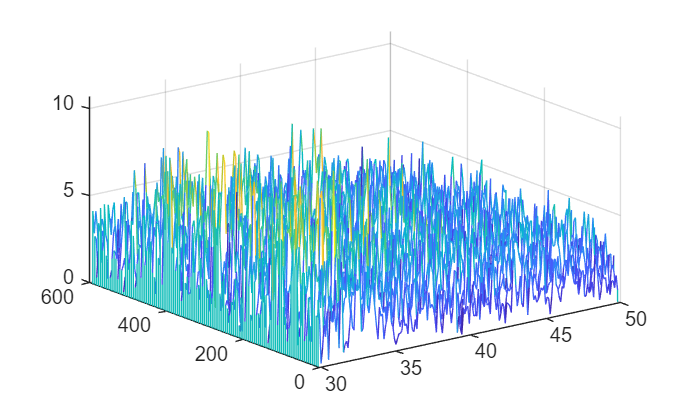

waterfall(prune_F,T,abs(prune_S(:,:,1))')

% waterfall(F,T,abs(S(:,:,1))')